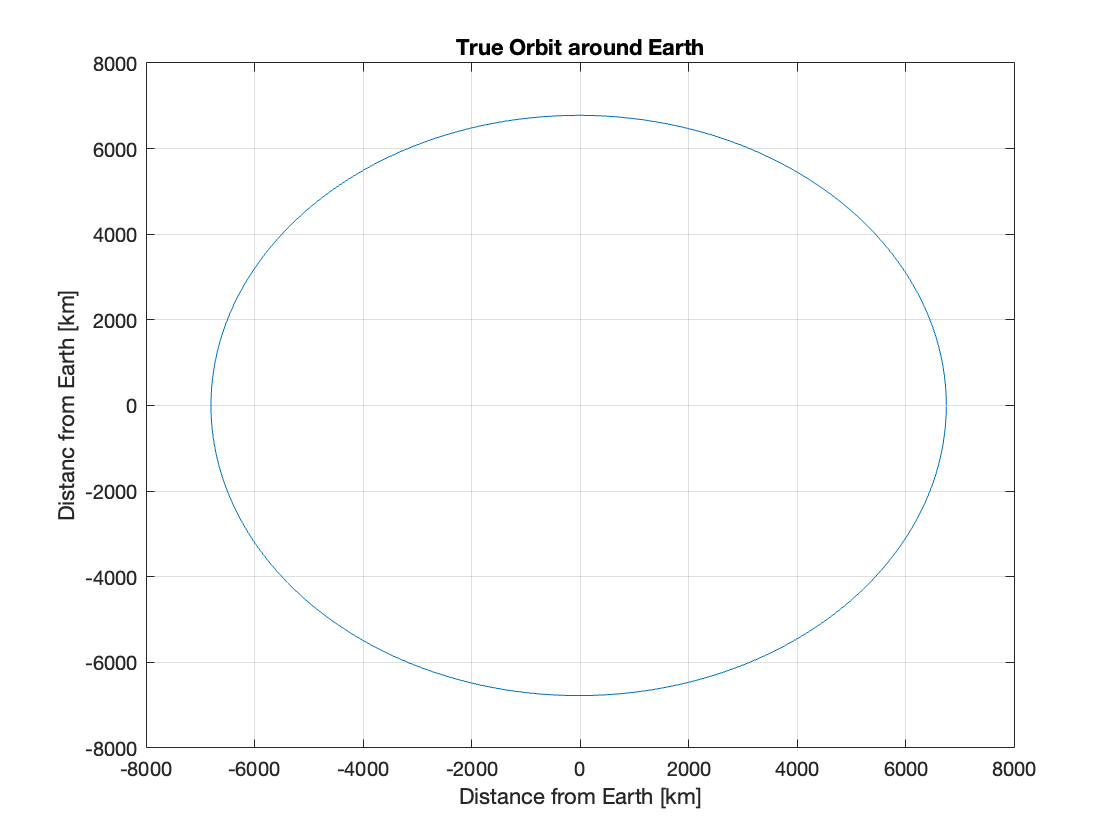

clear;
clear all;
clc;
rng('default')
% initialize variables


mu = 3.986004418e5; %gravitaitonal parameter [km^3/s^2]
wr = 10^(-8); % process noise for rdot [km/s] 
wtheta = 10^(-16); % process noise for thetadot [rad/s]
t0 = 0; %initial time [s]
dt = 30; % time between measurements [s]
x0_true = [6753.137;0;0;0.00113975]; % true initial state [km,km/s,rad,rad/s]
% calculate one orbital period using true initial state
energy0 = 1/2*(x0_true(2)^2+x0_true(1)^2*x0_true(4)^2) - mu/x0_true(1); %specific energy [km^2/s^2]
a0 = -mu/(2*energy0); %semi major axis [km]
period = 2*pi*sqrt(a0^3/mu); % orbital period [s]
tf = period; % end and one period [s]
t = t0:dt:tf; % array of time steps [s]
num_time_steps = length(t); % number of time steps
num_states = length(x0_true); % number of states
meas_dim = 2; % 1 measured state, theta
std_theta = 1e-2; %[rad] % measurement noise
R = diag([10,std_theta^2]); % measurement noise covariance 
R_chol = chol(R,'lower'); % standard deviation of measurement noise
H = [1, 0, 0, 0;0 0 1 0]; % measurement matrix
Q = [wr,0;0,wtheta]; % process noise covariance matrix
Q_chol = chol(Q,'lower'); % process noise standard deviation
G = [0,0;1,0;0,0;0,1]; % mapping matrix

% Prepopulate process noise with frequency 10 Hz
process_freq = 0.10;
t_process = t0:process_freq:tf;
random_wr = NaN(1,length(t_process));
random_wtheta = NaN(1,length(t_process)); 
for i = 1:length(t_process)
    random_wr(i) = randn;
    random_wtheta(i) = randn;
end
%% propagate true states
ode_opts = odeset('RelTol',1e-6,'AbsTol',1e-6);
[t,x_true] = ode45(@true_states,t,x0_true,ode_opts,num_states,mu,wr,wtheta,random_wr,random_wtheta,t_process);
figure()
x_true = x_true.';
% plot true state trajectory
plot(x_true(1,:).*cos(x_true(3,:)),x_true(1,:).*sin(x_true(3,:)),'')
grid on
title('True Orbit around Earth')
xlabel('Distance from Earth [km]')
ylabel('Distanc from Earth [km]')

## simulate measurements


Z = NaN(meas_dim,num_time_steps);
for k = 2:num_time_steps
        %if (rem(k,2) == 0)
            Z(:,k) = H * x_true(:,k) + R_chol * [randn;randn];            
       % end

end
% initial state estimates
m0_r = 6.75681367e3; % km
m0_rdot = -1.37015864e-1; %km/s
m0_theta = 4.45127583e-2; %rad
m0_thetadot = 1.08593276e-3; %rad/s
m0 = [m0_r,m0_rdot,m0_theta,m0_thetadot].'; % initial state  estimate vector
P0 = diag([40,1e-2,1e-3,1e-8]); % initial estimation error covariance
% preallocate memory for arrays storing information for each time step
mkm_hist = NaN(num_states,num_time_steps); % array of all priori estimates
mkp_hist = NaN(num_states,num_time_steps); % array of all posteriori estimates
Pkm_hist = NaN(num_states,num_states,num_time_steps); % array of all priori estimation error covariances
Pkp_hist = NaN(num_states,num_states,num_time_steps); % array of all posteriori covariances
Wk_hist = NaN(meas_dim,meas_dim,num_time_steps); % inovations matrix
Ck_hist = NaN(num_states,meas_dim,num_time_steps); % Cross covariance matrix
Kk_hist = NaN(num_states,meas_dim,num_time_steps); % Kalman gain matrix
mkp_hist(:,1) = m0; 
Pkp_hist(:,:,1) = P0;
% Uncented perams for scaled unscented transform
alpha = 0.001;
beta = 2;
kappa = 3-num_states;
lambda = alpha^2*(num_states + kappa) - num_states;
% set initial posteriori k-1 values
mkm1 = m0; 
Pkm1 = P0;
tkm1 = t0;
sigma_km1 = NaN(num_states,num_states*2+1);
sigma_km = NaN(num_states,num_states*2+1);
sigma_dyn = NaN(num_states,num_states*2+1);
sigma_meas = NaN(num_states,num_states*2+1);

weights_mean = NaN(1,num_states*2+1);
weights_cov = NaN(1,num_states*2+1);

weights_mean(1) = lambda / (num_states + lambda);
weights_mean(2:end) = 1 / (2*(num_states+lambda));
weights_cov(1) = lambda / (num_states + lambda) + (1-alpha^2+beta);
weights_cov(2:end) = 1 / (2*(num_states+lambda));
% UKF
for i = 2:num_time_steps
    tk = t(i);
    zk = Z(:,i);
    tspan = [tkm1,tk];
    % calc square root factor
    P_chol = chol(Pkm1,'lower');
    % calc sigma points from previous time step output
    sigma_km1(:,1) = mkm1;
    for l = 2:num_states+1
        sigma_km1(:,l) = mkm1 + sqrt(num_states+lambda)*P_chol(:,l-1);
        sigma_km1(:,l+num_states) = mkm1 - sqrt(num_states + lambda)*P_chol(:,l-1);
    end
    % calculate new apriori prediction sigma points
    for l = 1:2*num_states+1
        [~,Y] = ode45(@EKF_x_integration,tspan,sigma_km1(:,l),ode_opts,num_states,mu,G,Q);    

        sigma_dyn(:,l) =  Y(end,1:num_states).';
    end
    % calculate apriori mean and covariance
    mkm = zeros(num_states,1);
    Pkm = zeros(num_states,num_states);

    for l = 1:num_states*2+1
        mkm = mkm + sigma_dyn(:,l).*weights_mean(l);
    end
    for l = 1:num_states*2+1

        Pkm = Pkm + (sigma_dyn(:,l)-mkm)*(sigma_dyn(:,l)-mkm).'.*weights_cov(l);
    end

    Pkm = Pkm + G*Q*G.';
    %  Calc update 
    % measurement sigma points
    sigma_km(:,1) = mkm;
    Pkm_chol = chol(Pkm,'lower');

    for l = 2:num_states+1
        sigma_km(:,l) = mkm + sqrt(num_states+lambda)*Pkm_chol(:,l-1);
        sigma_km(:,l+num_states) = mkm - sqrt(num_states+lambda)*Pkm_chol(:,l-1);
    end    
    zk_hat = zeros(meas_dim,1);
    Wk = zeros(meas_dim,meas_dim);
    Ck = zeros(num_states,meas_dim);
    % prop sigmas through measurement  and compute gains
    for l = 1:num_states*2+1
        Zk(:,l) = H * sigma_km(:,l); 
        zk_hat = zk_hat + weights_mean(l) .*Zk(:,l);
    end
    for l = 1:num_states*2+1

        Wk = Wk + weights_cov(l).*(Zk(:,l) - zk_hat)*(Zk(:,l) - zk_hat).';
        Ck = Ck + weights_cov(l).*(sigma_km(:,l) - mkm)*(Zk(:,l) - zk_hat).';

    end
    Wk = Wk + R;
    % calculate posterior state
    Kk = Ck/Wk;
    mkp = mkm + Kk*(zk-zk_hat);
    Pkp = Pkm - Ck*Kk.' - Kk*Ck.' + Kk*Wk*Kk.';
    Pkp = 1/2*(Pkp+Pkp.');


    % store values
    mkm_hist(:,i) = mkm;
    mkp_hist(:,i) = mkp;
    Pkm_hist(:,:,i) = Pkm;
    Pkp_hist(:,:,i) = Pkp;
    Wk_hist(:,:,i) = Wk;
    Ck_hist(:,:,i) = Ck;
    Kk_hist(:,:,i) = Kk;
    t_span_hist(:,i) = tspan;
    %recursion
    mkm1 = mkp;
    Pkm1 =Pkp;
    tkm1 = tk;
end

## analysis

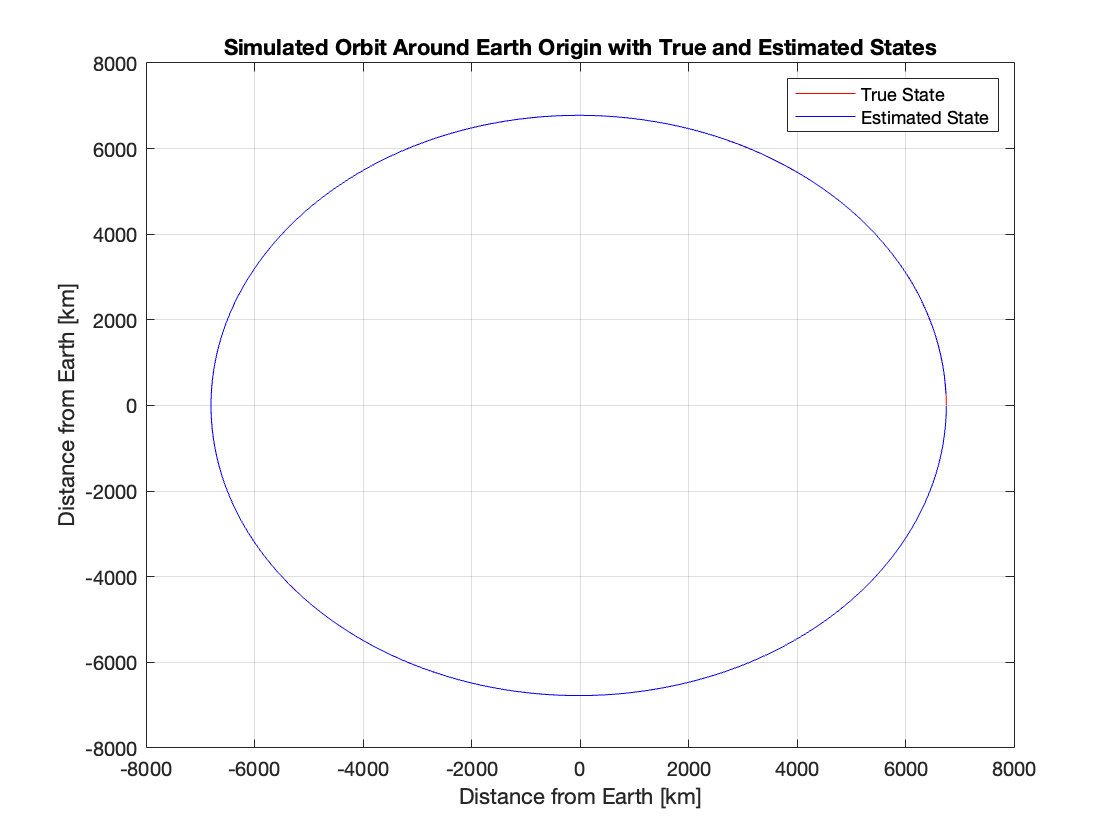

figure()
plot(x_true(1,:).*cos(x_true(3,:)),x_true(1,:).*sin(x_true(3,:)), 'red')
hold on
plot(mkp_hist(1,:).*cos(mkp_hist(3,:)),mkp_hist(1,:).*sin(mkp_hist(3,:)),'blue')
title('Simulated Orbit Around Earth Origin with True and Estimated States')
xlabel('Distance from Earth [km]')
ylabel('Distance from Earth [km]')
legend( 'True State','Estimated State')

grid on

t = reshape([t;t],[],length(t)*2);


## errors

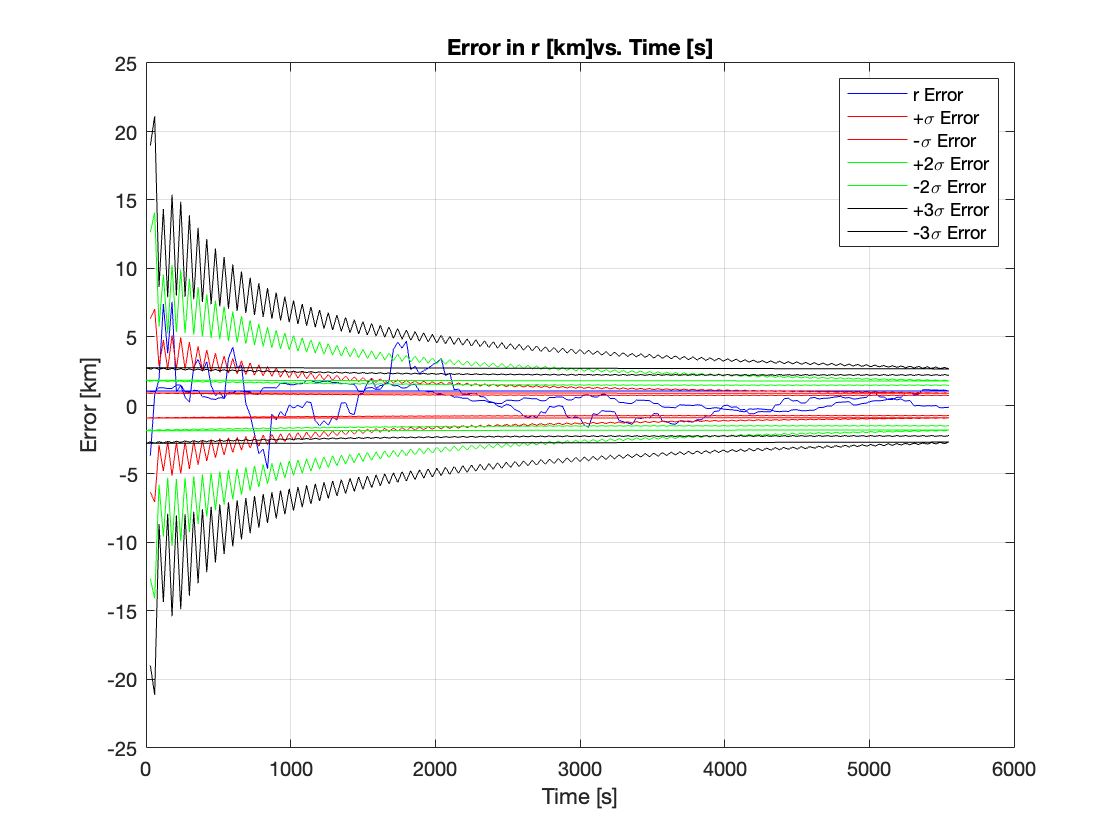

% get errors
%posteriori
error_r_p =  x_true(1,:) - mkp_hist(1,:);
error_r_dot_p =  x_true(2,:) - mkp_hist(2,:);
error_theta_p = x_true(3,:) - mkp_hist(3,:);
error_theta_dot_p = x_true(4,:) - mkp_hist(4,:);
r_dot_cov_p = reshape(sqrt(Pkp_hist(2,2,:)),num_time_steps,1).';
r_cov_p = reshape(sqrt(Pkp_hist(1,1,:)),num_time_steps,1).';
theta_cov_p = reshape(sqrt(Pkp_hist(3,3,:)),num_time_steps,1).';
theta_dot_cov_p = reshape(sqrt(Pkp_hist(4,4,:)),num_time_steps,1).';
%priori
error_r_m = x_true(1,:) - mkm_hist(1,:);
error_r_dot_m = x_true(2,:) - mkm_hist(2,:);
error_theta_m = x_true(3,:) - mkm_hist(3,:);
error_theta_dot_m = x_true(4,:) - mkm_hist(4,:);
r_dot_cov_m = reshape(sqrt(Pkm_hist(2,2,:)),num_time_steps,1).';
r_cov_m = reshape(sqrt(Pkm_hist(1,1,:)),num_time_steps,1).';
theta_cov_m = reshape(sqrt(Pkm_hist(3,3,:)),num_time_steps,1).';
theta_dot_cov_m = reshape(sqrt(Pkm_hist(4,4,:)),num_time_steps,1).';
% reshape to have both priori and posteriori values for same time
error_r = reshape([error_r_m;error_r_p],[],2*length(error_r_m));
error_r_dot = reshape([error_r_dot_m;error_r_dot_p],[],2*length(error_r_dot_m));
error_theta = reshape([error_theta_m;error_theta_p],[],2*length(error_theta_m));
error_theta_dot = reshape([error_theta_dot_m;error_theta_dot_p],[],2*length(error_theta_dot_m));
r_cov = reshape([r_cov_m;r_cov_p],[],2*length(r_cov_m));
r_dot_cov = reshape([r_dot_cov_m;r_dot_cov_p],[],2*length(r_dot_cov_m));
theta_cov = reshape([theta_cov_m;theta_cov_p],[],2*length(theta_cov_m));
theta_dot_cov = reshape([theta_dot_cov_m;theta_dot_cov_p],[],2*length(theta_dot_cov_m));







% r error
figure()
plot(t,reshape([error_r_m;error_r_p],[],2*length(error_r_m)),'blue')
hold on
plot(t,r_cov*1,'red')
plot(t,-r_cov*1,'red')
plot(t,r_cov*2,'green')
plot(t,-r_cov*2,'green')
plot(t,r_cov*3,'black')
plot(t,-r_cov*3,'black')
title('Error in r [km]vs. Time [s]')
xlabel('Time [s]')
ylabel('Error [km]')
legend('r Error', '+\sigma Error','-\sigma Error','+2\sigma Error','-2\sigma Error','+3\sigma Error','-3\sigma Error')

grid on

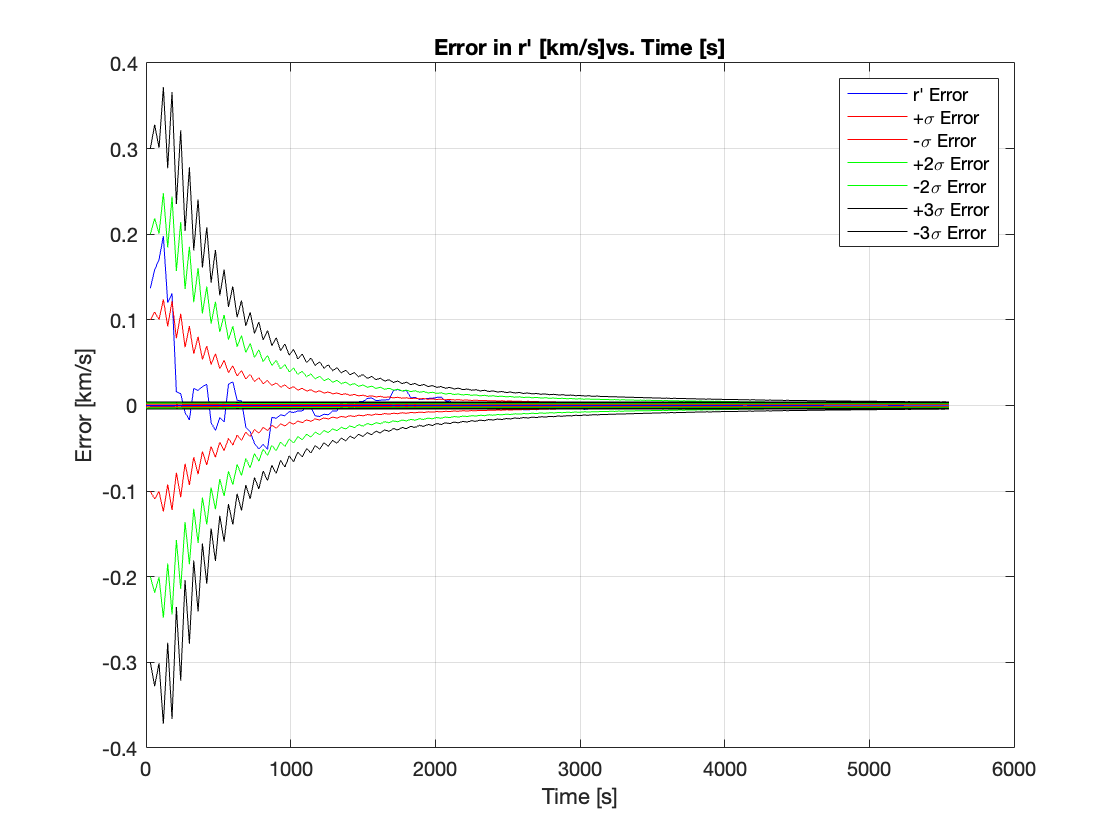


% rdot error
figure()
plot(t,error_r_dot,'blue')
hold on
plot(t,r_dot_cov*1,'red')
plot(t,-r_dot_cov*1,'red')
plot(t,r_dot_cov*2,'green')
plot(t,-r_dot_cov*2,'green')
plot(t,r_dot_cov*3,'black')
plot(t,-r_dot_cov*3,'black')
title('Error in r'' [km/s]vs. Time [s]')
xlabel('Time [s]')
ylabel('Error [km/s]')
legend('r'' Error', '+\sigma Error','-\sigma Error','+2\sigma Error','-2\sigma Error','+3\sigma Error','-3\sigma Error')

grid on

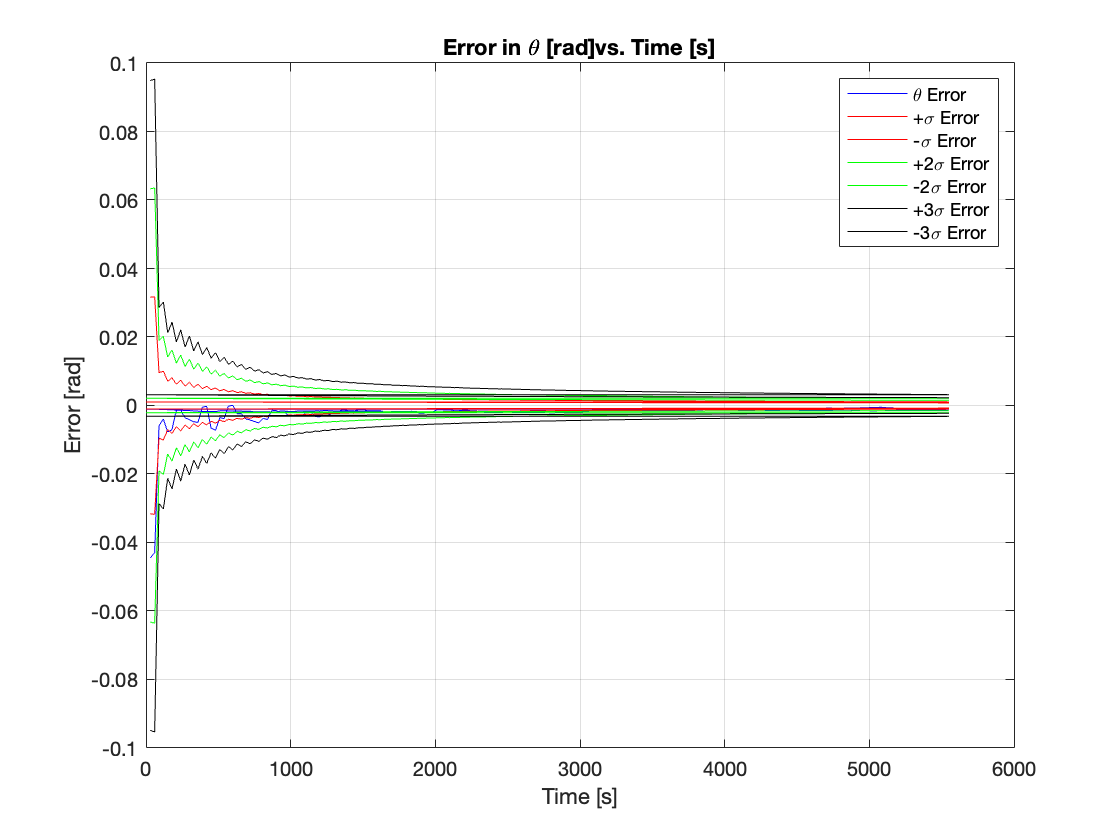

% theta error
figure()
plot(t,error_theta,'blue')
hold on
plot(t,theta_cov*1,'red')
plot(t,-theta_cov*1,'red')
plot(t,theta_cov*2,'green')
plot(t,-theta_cov*2,'green')
plot(t,theta_cov*3,'black')
plot(t,-theta_cov*3,'black')
title('Error in \theta [rad]vs. Time [s]')
xlabel('Time [s]')
ylabel('Error [rad]')
legend('\theta Error', '+\sigma Error','-\sigma Error','+2\sigma Error','-2\sigma Error','+3\sigma Error','-3\sigma Error')

grid on

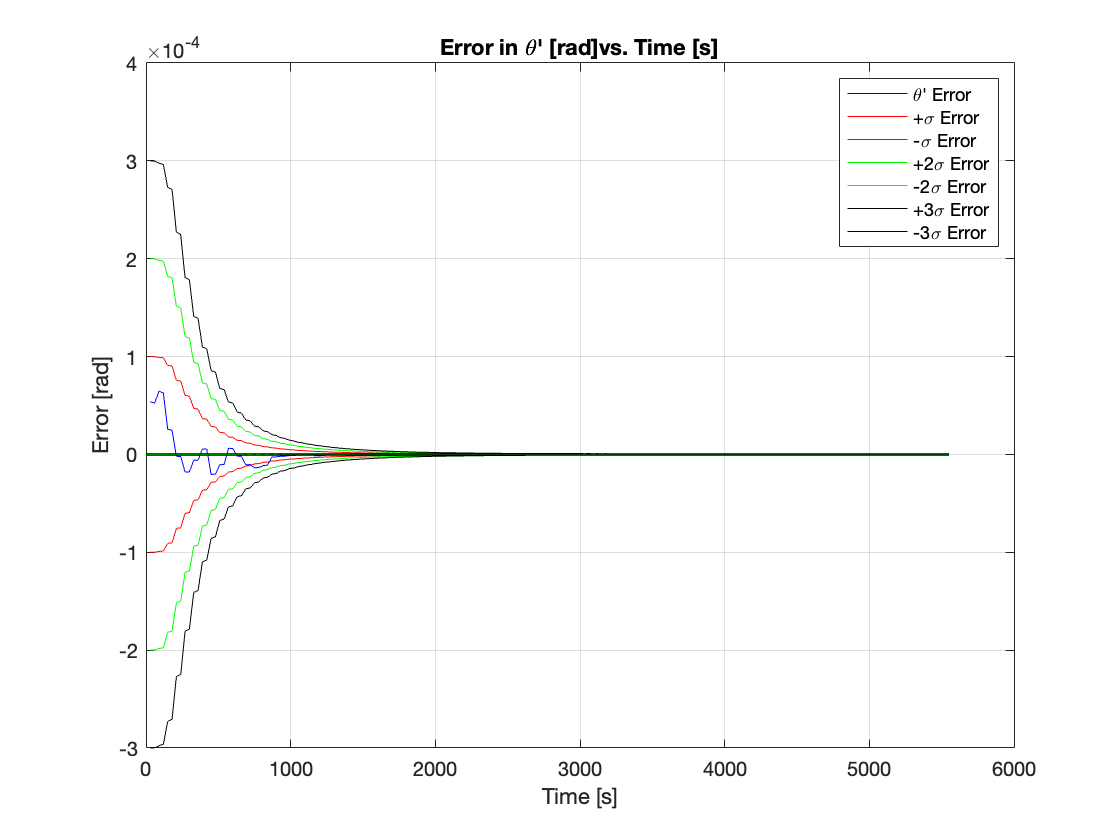

% theta dot error
figure()
plot(t,error_theta_dot,'blue')
hold on
plot(t,theta_dot_cov*1,'red')
plot(t,-theta_dot_cov*1,'red')
plot(t,theta_dot_cov*2,'green')
plot(t,-theta_dot_cov*2,'green')
plot(t,theta_dot_cov*3,'black')
plot(t,-theta_dot_cov*3,'black')
title('Error in \theta'' [rad]vs. Time [s]')
xlabel('Time [s]')
ylabel('Error [rad]')
legend('\theta'' Error', '+\sigma Error','-\sigma Error','+2\sigma Error','-2\sigma Error','+3\sigma Error','-3\sigma Error')

grid on

function [x_dot] = true_states(time,x,num_states,mu,wr,wtheta,random_wr,random_theta,t_process)
    r = x(1);
    r_dot = x(2);
    theta = x(3);
    theta_dot = x(4);
    
    x_dot(1,1) = r_dot;
    x_dot(2,1) = r*theta_dot^2-mu/r^2  + sqrt(wr) * random_wr(find(t_process<=time,1,'last'));
    x_dot(3,1) =  theta_dot;
    x_dot(4,1) = -2*theta_dot*r_dot/r  + sqrt(wtheta)*random_theta(find(t_process<=time,1,'last'));
end
    function [x_dot] = EKF_x_integration(time,x,num_states,mu,G,Q)
    r = x(1);
    r_dot = x(2);
    theta = x(3);
    theta_dot = x(4);
    
    x_dot(1,1) = r_dot;
    x_dot(2,1) = r*theta_dot^2-mu/r^2;
    x_dot(3,1) =  theta_dot;
    x_dot(4,1) = -2*theta_dot*r_dot/r;
    if length(x) > num_states
        P = reshape(x(num_states+1:end),num_states,num_states);
        F = jacobian_compile(r,r_dot,theta,theta_dot,mu);

        P_dot = F*P + P*F.' + G*Q*G.';
        x_dot(5:20,1) = P_dot(:);
    end

end
function F = jacobian_compile(r,r_dot,theta,theta_dot,mu)
    F = [0,1,0,0;...
        theta_dot^2 + 2*mu/r^3,0,0,2*theta_dot*r;...
        0,0,0,1;...
        2*theta_dot*r_dot/r^2,-2*theta_dot/r,0,-2*r_dot/r];

end
